
开始对 5 个并行换热单元逐级仿真 ...
  -> 第 1 级: Tf=309.000 °C, mdot=0.469000 kg/s, Ts0=290.000 °C

================= 稳态输出参数 =================
稳态储热温度 Ts_ss           = 306.4746 K
稳态输入热量 Qin_ss          = 4974.5002 W
稳态散热量 Qloss_ss          = 4953.9533 W
净热量（应接近0）Qnet_ss     = 20.5469 W
最后时刻温度变化率 dTs/dt    = 0.000038 K/s
稳态判定：系统已达到稳态 √



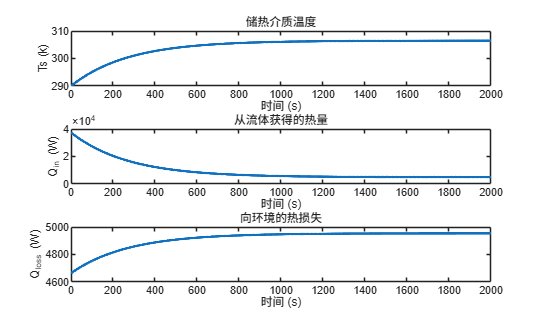

      -> 本级最终 Ts = 306.4746 °C, 累计净换热 = 8879.922 kJ
  -> 第 2 级: Tf=325.000 °C, mdot=0.469000 kg/s, Ts0=290.000 °C

================= 稳态输出参数 =================
稳态储热温度 Ts_ss           = 322.3230 K
稳态输入热量 Qin_ss          = 5273.1972 W
稳态散热量 Qloss_ss          = 5232.8844 W
净热量（应接近0）Qnet_ss     = 40.3128 W
最后时刻温度变化率 dTs/dt    = 0.000075 K/s
稳态判定：系统已达到稳态 √



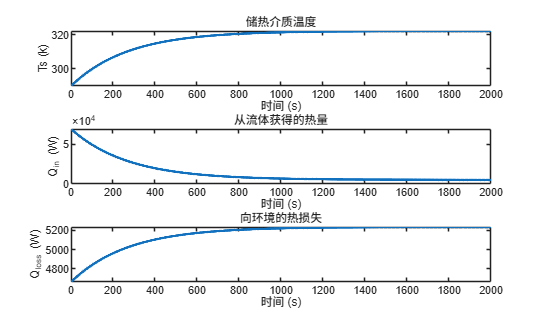

      -> 本级最终 Ts = 322.3230 °C, 累计净换热 = 17422.289 kJ
  -> 第 3 级: Tf=342.000 °C, mdot=0.469000 kg/s, Ts0=290.000 °C

================= 稳态输出参数 =================
稳态储热温度 Ts_ss           = 339.1619 K
稳态输入热量 Qin_ss          = 5590.5628 W
稳态散热量 Qloss_ss          = 5529.2488 W
净热量（应接近0）Qnet_ss     = 61.3140 W
最后时刻温度变化率 dTs/dt    = 0.000114 K/s
稳态判定：尚未完全达到稳态 ×（可增加模拟时间）



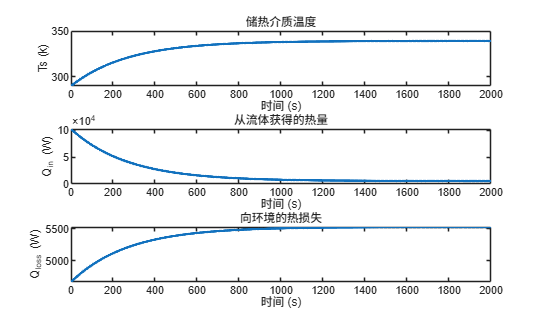

      -> 本级最终 Ts = 339.1619 °C, 累计净换热 = 26498.554 kJ
  -> 第 4 级: Tf=360.000 °C, mdot=0.469000 kg/s, Ts0=290.000 °C

================= 稳态输出参数 =================
稳态储热温度 Ts_ss           = 356.9913 K
稳态输入热量 Qin_ss          = 5926.5970 W
稳态散热量 Qloss_ss          = 5843.0463 W
净热量（应接近0）Qnet_ss     = 83.5506 W
最后时刻温度变化率 dTs/dt    = 0.000155 K/s
稳态判定：尚未完全达到稳态 ×（可增加模拟时间）



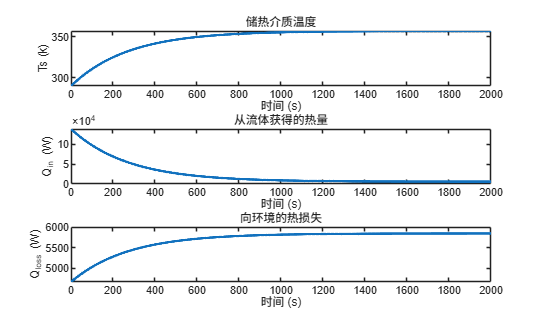

      -> 本级最终 Ts = 356.9913 °C, 累计净换热 = 36108.716 kJ
  -> 第 5 级: Tf=371.000 °C, mdot=0.469000 kg/s, Ts0=290.000 °C

================= 稳态输出参数 =================
稳态储热温度 Ts_ss           = 367.8870 K
稳态输入热量 Qin_ss          = 6131.9512 W
稳态散热量 Qloss_ss          = 6034.8115 W
净热量（应接近0）Qnet_ss     = 97.1397 W
最后时刻温度变化率 dTs/dt    = 0.000181 K/s
稳态判定：尚未完全达到稳态 ×（可增加模拟时间）



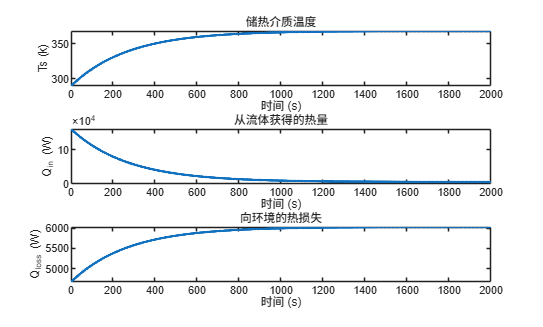

      -> 本级最终 Ts = 367.8870 °C, 累计净换热 = 41981.594 kJ

============= 多级并行汇总 =============
总质量流量 mdot_total = 2.345000 kg/s
总累计净换热量 Q_total = 130891.075 kJ
各级最终 Ts: 306.475 322.323 339.162 356.991 367.887  °C
按各级储热质量加权合并温度 = 338.5675 °C
与主罐混合后温度 = 301.8436 °C (主罐 M=2000.000 kg, cp=4186.0 J/kg·°C, T0=290.000 °C)



% ===== 热罐总换热测试代码=====
% 系统参数
Tf   = [309, 325, 342, 360, 371];     % K
mdot = 0.469 * ones(1,5);             % kg/s
N = 5;

cp_f = 4200;       % J/(kg·°C)
Tenv = 25;
U = 8;
A = 2.2;
M_stage = 600;     % 每级储热体质量（假设相同） kg
cp_s = 900;
Ts0_list = 290 * ones(1,5);
t_end = 2000;

% 如果你有主罐参数，可以传入：
M_main = 2000;     % kg
cp_main = 4186;    % J/(kg·°C)
T_main0 = 290;     % °C

res = multistage_storage_out(Tf, mdot, N, cp_f, Tenv, U, A, M_stage, cp_s, ...
        Ts0_list, t_end, M_main, cp_main, T_main0);